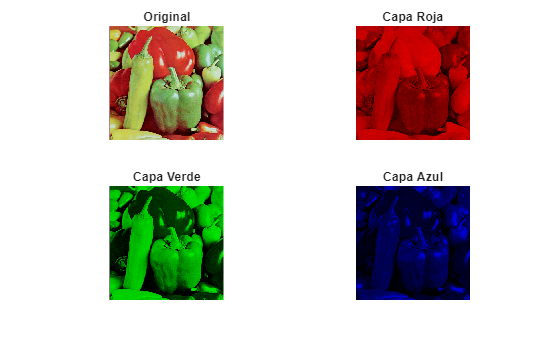

clc; clear; close all;
tic

%% ===== LECTURA Y SEPARACIÓN RGB =====
img = imread('C:\Users\NIKO\Documents\GitHub\NEQR_Tests\ImplementacionCompleta\Peppers.jpg');
rojo  = img(:,:,1);
verde = img(:,:,2);
azul  = img(:,:,3);
[filas, columnas, ~] = size(img);

lienzo_negro = zeros(filas, columnas, 3, 'uint8');
img_roja  = lienzo_negro; img_roja(:,:,1)  = rojo;
img_verde = lienzo_negro; img_verde(:,:,2) = verde;
img_azul  = lienzo_negro; img_azul(:,:,3)  = azul;

figure;
subplot(2,2,1); imshow(img);       title('Original')
subplot(2,2,2); imshow(img_roja);  title('Capa Roja')
subplot(2,2,3); imshow(img_verde); title('Capa Verde')
subplot(2,2,4); imshow(img_azul);  title('Capa Azul')

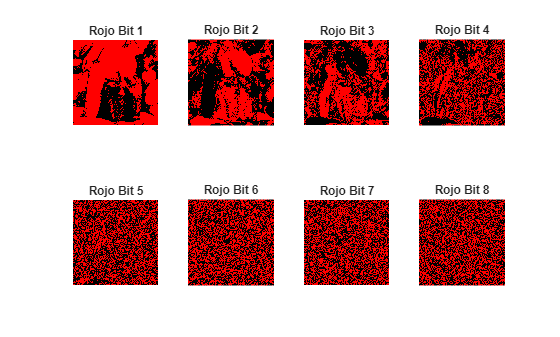


%% ===== PARÁMETROS GLOBALES =====
x0_key  = -0.2;  y0_key  = 0.4;  z0_key  = 0.7;
N0_chen = 1000;
N_pixel = filas * columnas;

x0_ca = x0_key + 0.333;
y0_ca = y0_key - 0.111;
z0_ca = z0_key + 0.777;
N0_ca = 500;

%% ===== PLANOS DE BITS ORIGINALES =====
rojo_bin  = zeros(filas, columnas, 8, 'logical');
verde_bin = zeros(filas, columnas, 8, 'logical');
azul_bin  = zeros(filas, columnas, 8, 'logical');
for k = 1:8
    rojo_bin(:,:,k)  = bitget(rojo,  9-k);
    verde_bin(:,:,k) = bitget(verde, 9-k);
    azul_bin(:,:,k)  = bitget(azul,  9-k);
end

mapa_rojo  = [0 0 0; 1 0 0];
mapa_verde = [0 0 0; 0 1 0];
mapa_azul  = [0 0 0; 0 0 1];

figure('Name','Planos Originales (ROJO)');
for k=1:8, subplot(2,4,k); imshow(rojo_bin(:,:,k)); colormap(gca,mapa_rojo); title(['Rojo Bit ',num2str(k)]); end

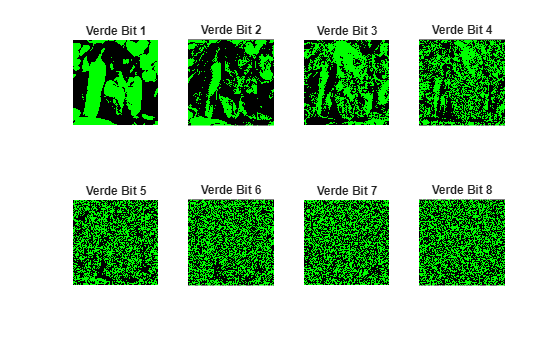

figure('Name','Planos Originales (VERDE)');
for k=1:8, subplot(2,4,k); imshow(verde_bin(:,:,k)); colormap(gca,mapa_verde); title(['Verde Bit ',num2str(k)]); end

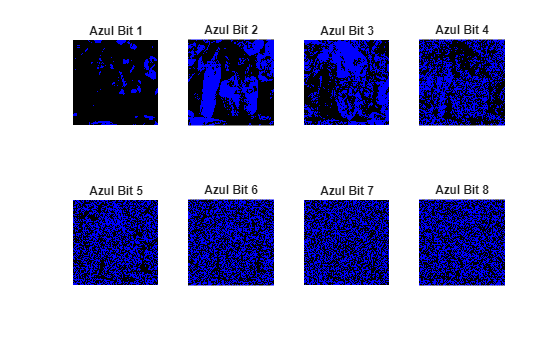

figure('Name','Planos Originales (AZUL)');
for k=1:8, subplot(2,4,k); imshow(azul_bin(:,:,k)); colormap(gca,mapa_azul); title(['Azul Bit ',num2str(k)]); end

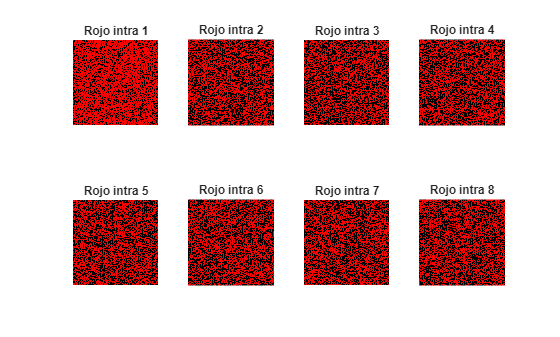


%% ===== INTRA-BIT =====
rojo_perm  = zeros(size(rojo_bin),  'logical');
verde_perm = zeros(size(verde_bin), 'logical');
azul_perm  = zeros(size(azul_bin),  'logical');

for k = 1:8
    z0_k = z0_key + (k-1) * 1e-4;
    [Sx_k, Sy_k, Sz_k] = chenSequence(x0_key, y0_key, z0_k, N0_chen, N_pixel);
    [bp_perm_R, Gmask, ~] = intraBitPermutation(rojo_bin(:,:,k), Sx_k);
    rojo_perm(:,:,k) = bp_perm_R;
    [bp_perm_G, ~, ~] = intraBitPermutation(verde_bin(:,:,k), Sy_k);
    verde_perm(:,:,k) = bp_perm_G;
    [bp_perm_B, ~, ~] = intraBitPermutation(azul_bin(:,:,k), Sz_k);
    azul_perm(:,:,k) = bp_perm_B;
end

figure('Name','Planos Intra-Bit (ROJO)');
for k=1:8, subplot(2,4,k); imshow(rojo_perm(:,:,k)); colormap(gca,mapa_rojo); title(['Rojo intra ',num2str(k)]); end

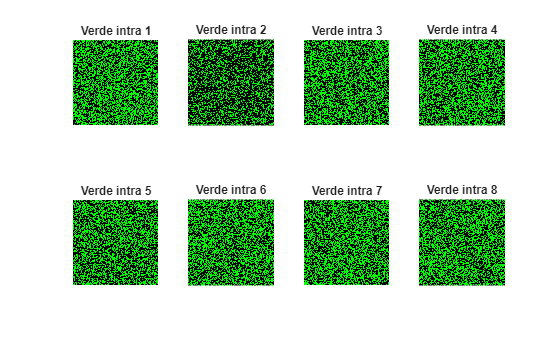

figure('Name','Planos Intra-Bit (VERDE)');
for k=1:8, subplot(2,4,k); imshow(verde_perm(:,:,k)); colormap(gca,mapa_verde); title(['Verde intra ',num2str(k)]); end

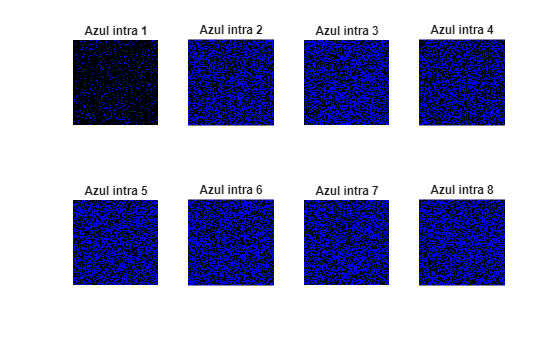

figure('Name','Planos Intra-Bit (AZUL)');
for k=1:8, subplot(2,4,k); imshow(azul_perm(:,:,k)); colormap(gca,mapa_azul); title(['Azul intra ',num2str(k)]); end

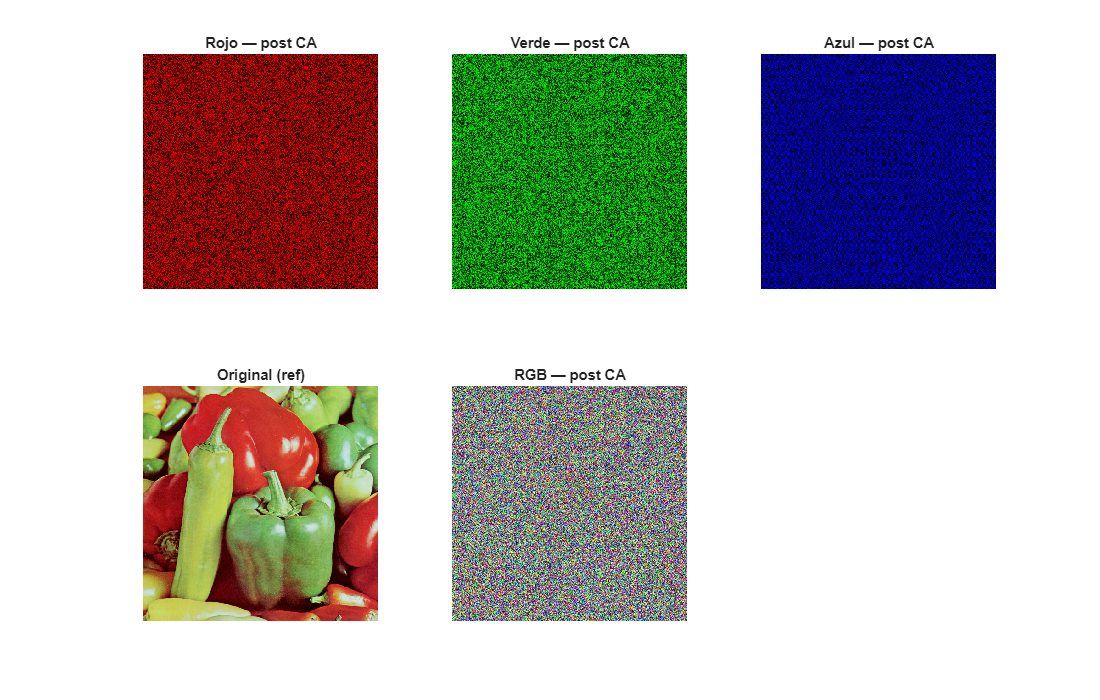


%% ===== RECONSTRUCCIÓN TRAS INTRA-BIT =====
R_reconstruido = zeros(filas, columnas, 'uint8');
G_reconstruido = zeros(filas, columnas, 'uint8');
B_reconstruido = zeros(filas, columnas, 'uint8');
for k = 1:8
    pos = 9 - k;
    R_reconstruido = bitset(R_reconstruido, pos, rojo_perm(:,:,k));
    G_reconstruido = bitset(G_reconstruido, pos, verde_perm(:,:,k));
    B_reconstruido = bitset(B_reconstruido, pos, azul_perm(:,:,k));
end

%% ===== ETAPA CA: AUTÓMATAS CELULARES =====
R_ca = cellularAutomatonEncryption(R_reconstruido, x0_ca, y0_ca, z0_ca,       N0_ca, true, false);
G_ca = cellularAutomatonEncryption(G_reconstruido, x0_ca, y0_ca, z0_ca + 0.1, N0_ca, true, false);
B_ca = cellularAutomatonEncryption(B_reconstruido, x0_ca, y0_ca, z0_ca + 0.2, N0_ca, true, false);

lienzo_negro = zeros(filas, columnas, 3, 'uint8');
R_ca_vis = lienzo_negro; R_ca_vis(:,:,1) = R_ca;
G_ca_vis = lienzo_negro; G_ca_vis(:,:,2) = G_ca;
B_ca_vis = lienzo_negro; B_ca_vis(:,:,3) = B_ca;
img_ca_rgb = cat(3, R_ca, G_ca, B_ca);

figure('Name','Canales tras Autómatas Celulares (CA)', 'Position', [100 100 1100 700]);
subplot(2,3,1); imshow(R_ca_vis);  title('Rojo — post CA',  'FontSize',11);
subplot(2,3,2); imshow(G_ca_vis);  title('Verde — post CA', 'FontSize',11);
subplot(2,3,3); imshow(B_ca_vis);  title('Azul — post CA',  'FontSize',11);
subplot(2,3,4); imshow(img);        title('Original (ref)',  'FontSize',11);
subplot(2,3,5); imshow(img_ca_rgb); title('RGB — post CA',   'FontSize',11);

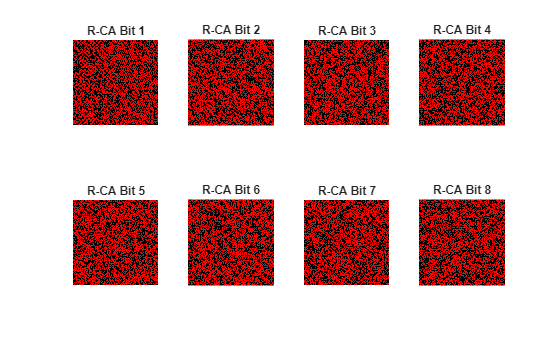


R_ca_planes = zeros(filas, columnas, 8, 'logical');
G_ca_planes = zeros(filas, columnas, 8, 'logical');
B_ca_planes = zeros(filas, columnas, 8, 'logical');
for k = 1:8
    R_ca_planes(:,:,k) = bitget(R_ca, 9-k);
    G_ca_planes(:,:,k) = bitget(G_ca, 9-k);
    B_ca_planes(:,:,k) = bitget(B_ca, 9-k);
end

figure('Name','Planos post-CA (ROJO)');
for k=1:8, subplot(2,4,k); imshow(R_ca_planes(:,:,k)); colormap(gca,mapa_rojo); title(['R-CA Bit ',num2str(k)]); end

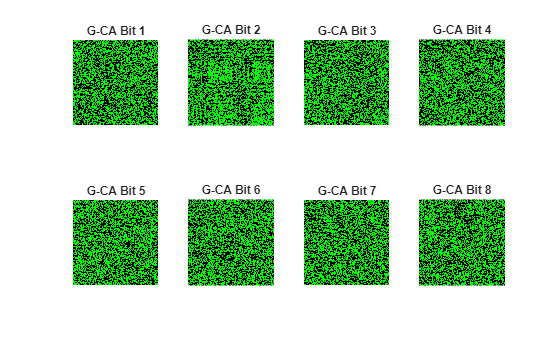

figure('Name','Planos post-CA (VERDE)');
for k=1:8, subplot(2,4,k); imshow(G_ca_planes(:,:,k)); colormap(gca,mapa_verde); title(['G-CA Bit ',num2str(k)]); end

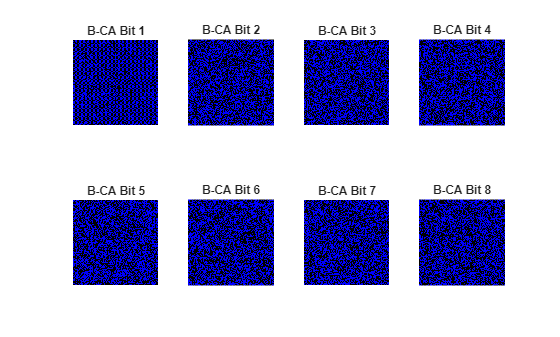

figure('Name','Planos post-CA (AZUL)');
for k=1:8, subplot(2,4,k); imshow(B_ca_planes(:,:,k)); colormap(gca,mapa_azul); title(['B-CA Bit ',num2str(k)]); end

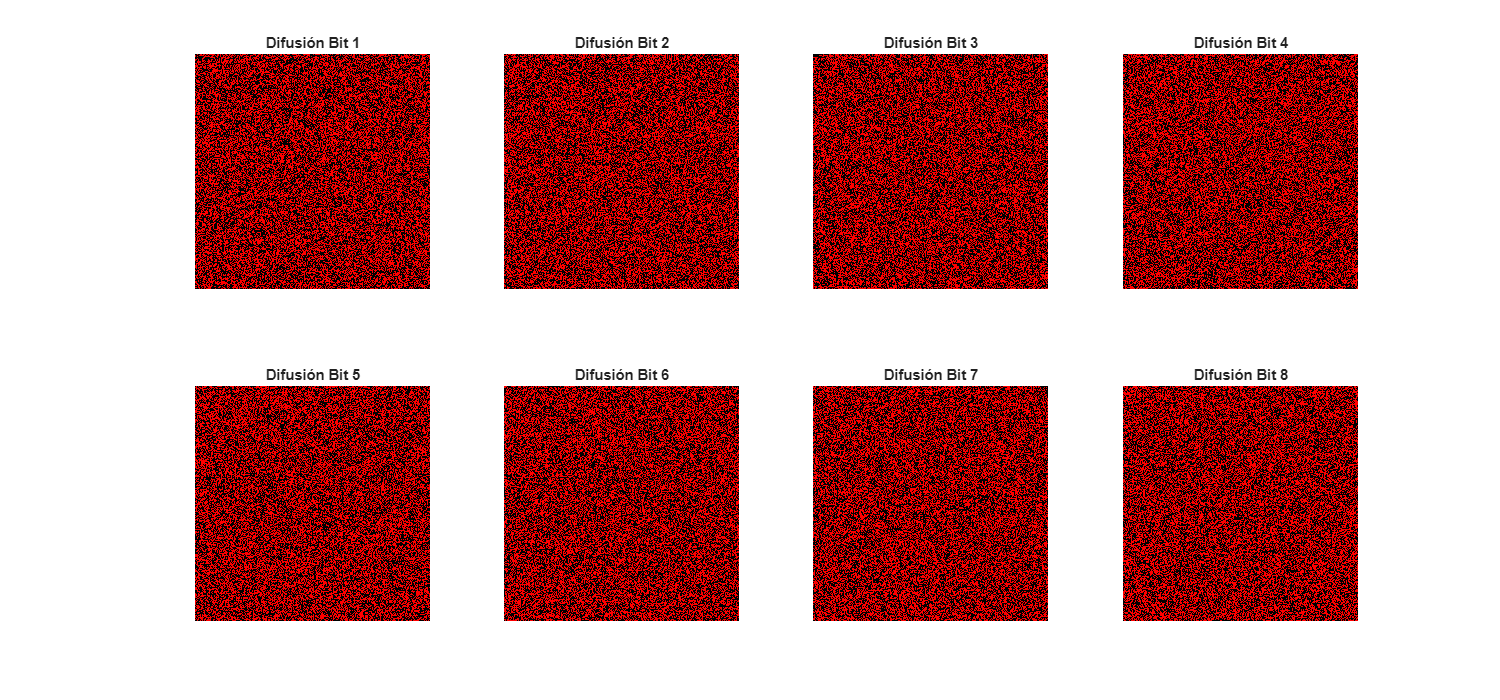


%% ===== DIFUSIÓN CUÁNTICA CAÓTICA (CON CIRCUITOS CUÁNTICOS) =====

% Generar secuencias caóticas para difusión
[Sx_diff, Sy_diff, Sz_diff] = chenSequence(x0_key, y0_key, z0_key + 0.1, N0_chen, N_pixel);

% Aplicar difusión
R_cifrado = chaoticDiffusion(R_ca, Sx_diff);
G_cifrado = chaoticDiffusion(G_ca, Sy_diff);
B_cifrado = chaoticDiffusion(B_ca, Sz_diff);
img_cifrada_final = cat(3, R_cifrado, G_cifrado, B_cifrado);

%% ===== VISUALIZACIÓN DE DIFUSIÓN CAÓTICA =====

% Crear lienzos RGB individuales
R_diff_vis = lienzo_negro;
R_diff_vis(:,:,1) = R_cifrado;

G_diff_vis = lienzo_negro;
G_diff_vis(:,:,2) = G_cifrado;

B_diff_vis = lienzo_negro;
B_diff_vis(:,:,3) = B_cifrado;

% ===== EXTRAER PLANOS POST-DIFUSIÓN =====
R_postDiff = zeros(filas, columnas, 8, 'logical');
G_postDiff = zeros(filas, columnas, 8, 'logical');
B_postDiff = zeros(filas, columnas, 8, 'logical');

for k = 1:8
    R_postDiff(:,:,k) = bitget(R_cifrado, 9-k);
    G_postDiff(:,:,k) = bitget(G_cifrado, 9-k);
    B_postDiff(:,:,k) = bitget(B_cifrado, 9-k);
end
%% =========================================================
%% ROJO
%% =========================================================

figure('Name','Difusión sobre Planos de Bits - ROJO', ...
       'Position',[100 100 1500 700]);

for k = 1:8
    subplot(2,4,k);
    imshow(R_postDiff(:,:,k));
    colormap(gca,mapa_rojo);
    title(['Difusión Bit ',num2str(k)]);
end

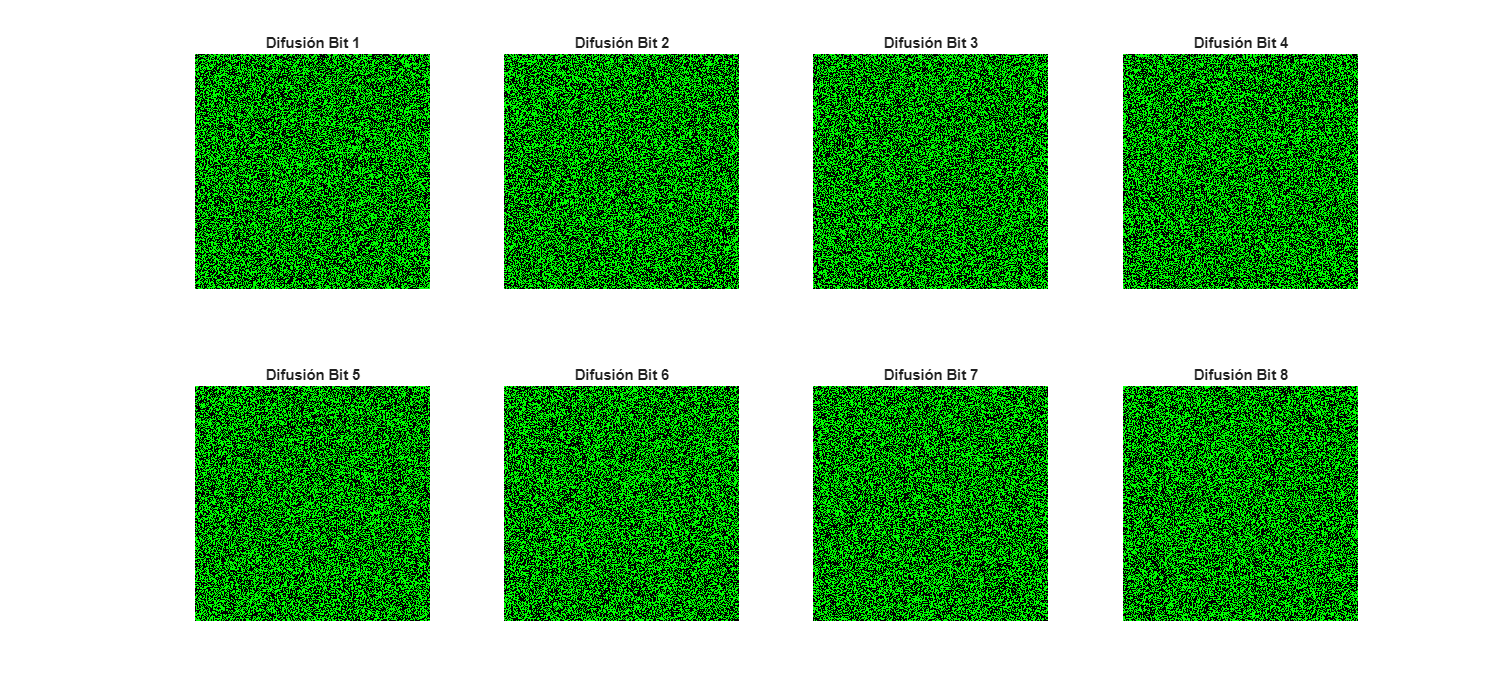


%% =========================================================
%% VERDE
%% =========================================================

figure('Name','Difusión sobre Planos de Bits - VERDE', ...
       'Position',[100 100 1500 700]);
for k = 1:8
    subplot(2,4,k);
    imshow(G_postDiff(:,:,k));
    colormap(gca,mapa_verde);
    title(['Difusión Bit ',num2str(k)]);
end

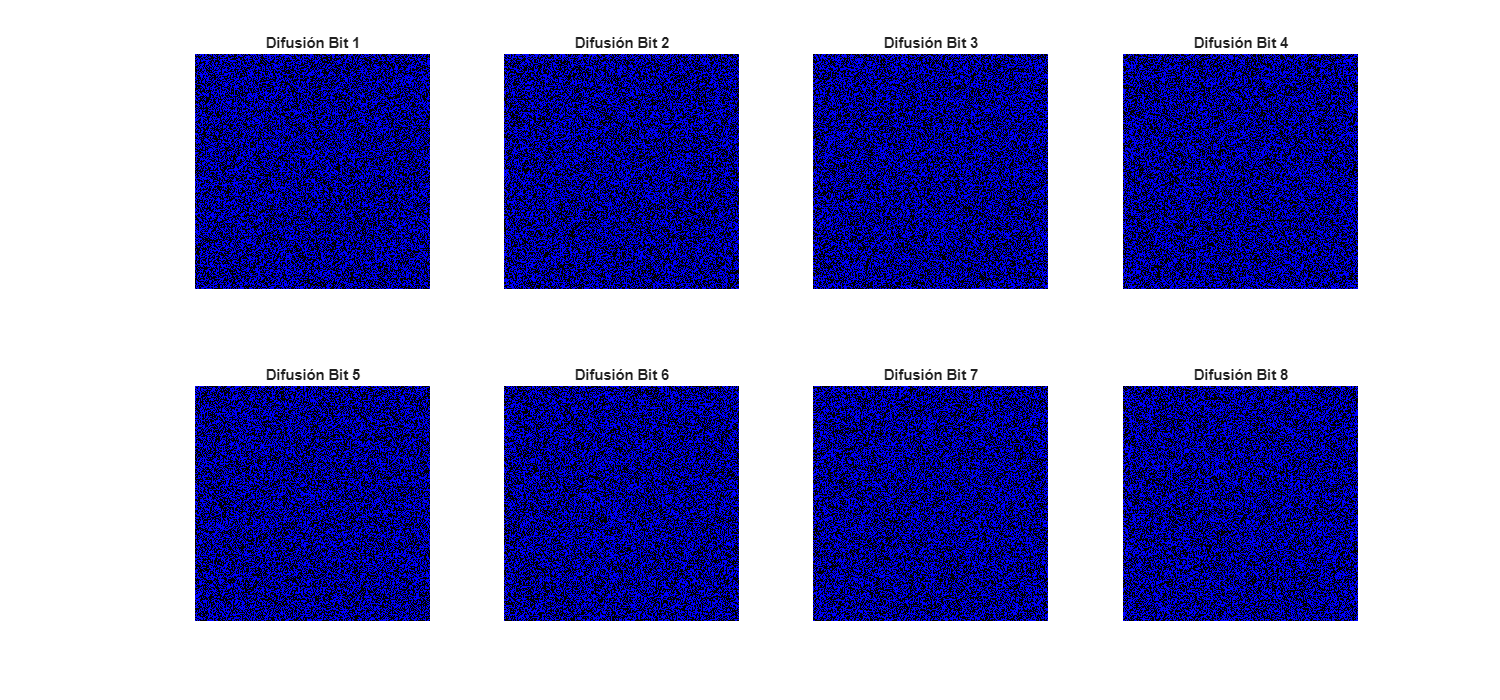


%% =========================================================
%% AZUL
%% =========================================================

figure('Name','Difusión sobre Planos de Bits - AZUL', ...
       'Position',[100 100 1500 700]);

for k = 1:8
    subplot(2,4,k);
    imshow(B_postDiff(:,:,k));
    colormap(gca,mapa_azul);
    title(['Difusión Bit ',num2str(k)]);
end

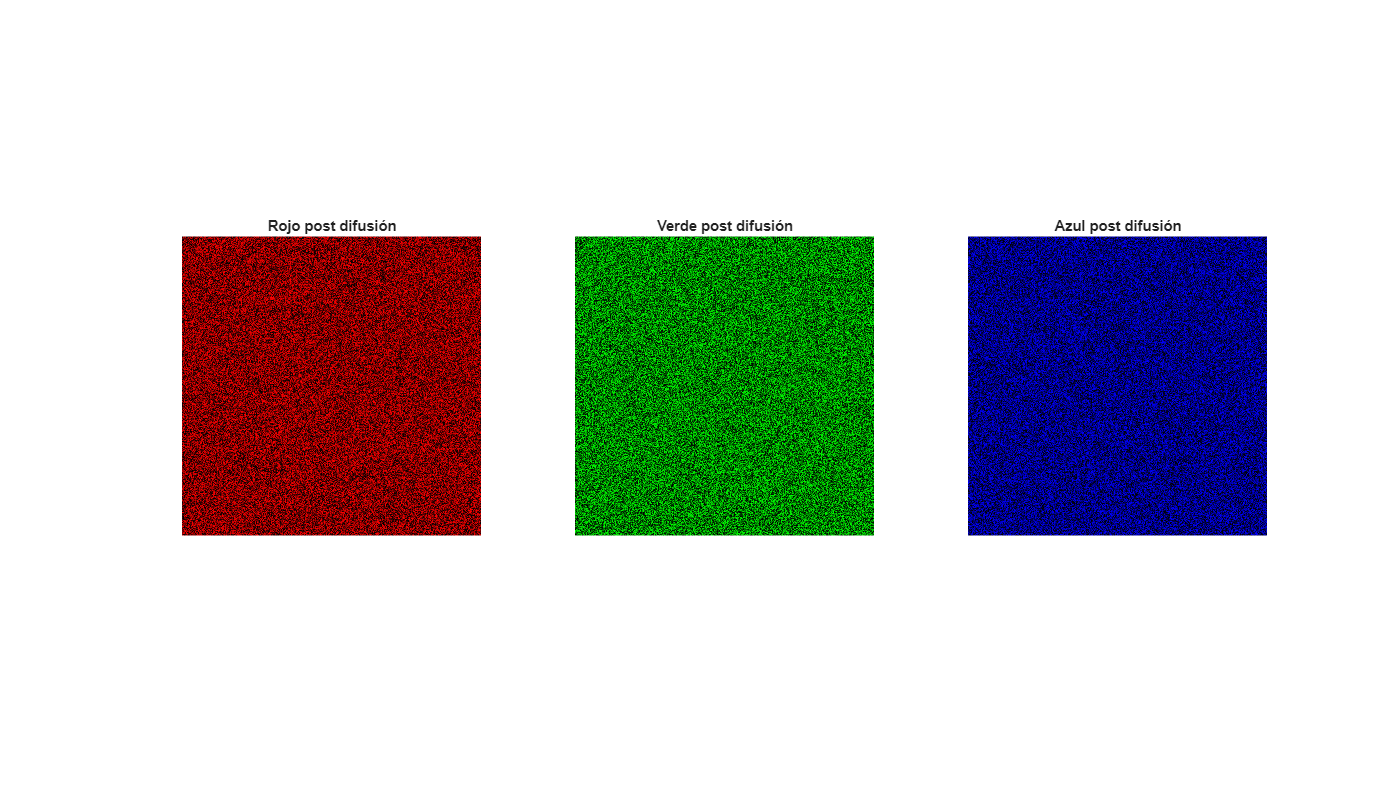


figure('Name','Difusión Caótica por Canal','Position',[100 100 1400 800]);

subplot(1,3,1);
imshow(R_diff_vis);
title('Rojo post difusión');

subplot(1,3,2);
imshow(G_diff_vis);
title('Verde post difusión');

subplot(1,3,3);
imshow(B_diff_vis);
title('Azul post difusión');

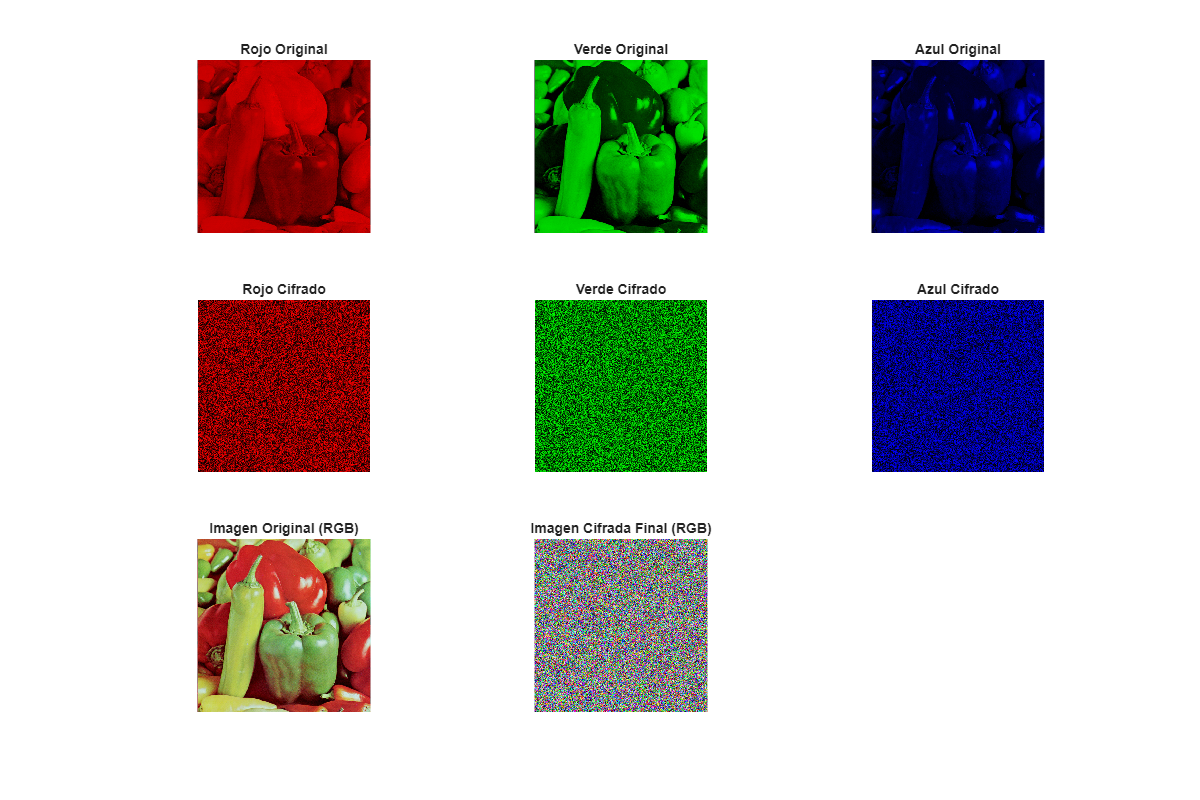


%% ===== VISUALIZACIÓN COMPARATIVA FINAL =====
R_cifr_vis = lienzo_negro; R_cifr_vis(:,:,1) = R_cifrado;
G_cifr_vis = lienzo_negro; G_cifr_vis(:,:,2) = G_cifrado;
B_cifr_vis = lienzo_negro; B_cifr_vis(:,:,3) = B_cifrado;

figure('Name','Comparativa de Encriptación','Position',[100 100 1200 800]);
subplot(3,3,1); imshow(img_roja);          title('Rojo Original');
subplot(3,3,2); imshow(img_verde);         title('Verde Original');
subplot(3,3,3); imshow(img_azul);          title('Azul Original');
subplot(3,3,4); imshow(R_cifr_vis);        title('Rojo Cifrado');
subplot(3,3,5); imshow(G_cifr_vis);        title('Verde Cifrado');
subplot(3,3,6); imshow(B_cifr_vis);        title('Azul Cifrado');
subplot(3,3,7); imshow(img);               title('Imagen Original (RGB)');
subplot(3,3,8); imshow(img_cifrada_final); title('Imagen Cifrada Final (RGB)');


%% =====================================================================
%% DESENCRIPTACIÓN
%% =====================================================================

fprintf('Aplicando descifrado cuántico con circuitos cuánticos...\n');

Aplicando descifrado cuántico con circuitos cuánticos...


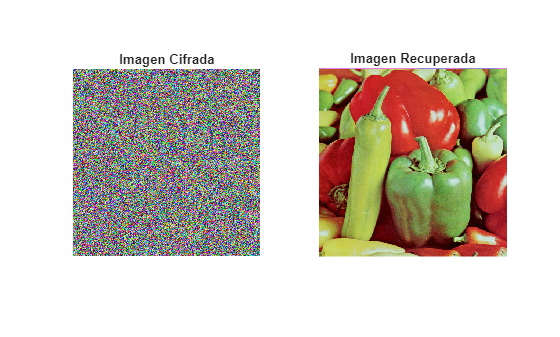


% 1. Invertir difusión cuántica (XOR es su propio inverso en el circuito)
R_perm_rec = inverseQuantumDiffusionWithCircuit(img_cifrada_final(:,:,1), Sx_diff);
G_perm_rec = inverseQuantumDiffusionWithCircuit(img_cifrada_final(:,:,2), Sy_diff);
B_perm_rec = inverseQuantumDiffusionWithCircuit(img_cifrada_final(:,:,3), Sz_diff);

% 2. Invertir autómatas celulares
R_ca_dec = cellularAutomatonEncryption(R_perm_rec, x0_ca, y0_ca, z0_ca,       N0_ca, false, false);
G_ca_dec = cellularAutomatonEncryption(G_perm_rec, x0_ca, y0_ca, z0_ca + 0.1, N0_ca, false, false);
B_ca_dec = cellularAutomatonEncryption(B_perm_rec, x0_ca, y0_ca, z0_ca + 0.2, N0_ca, false, false);

% 3. Invertir permutación intra-bit
bitplanes_R = zeros(filas, columnas, 8, 'logical');
bitplanes_G = zeros(filas, columnas, 8, 'logical');
bitplanes_B = zeros(filas, columnas, 8, 'logical');
for k = 1:8
    bitplanes_R(:,:,k) = logical(bitget(R_ca_dec, 9-k));
    bitplanes_G(:,:,k) = logical(bitget(G_ca_dec, 9-k));
    bitplanes_B(:,:,k) = logical(bitget(B_ca_dec, 9-k));
end

for k = 1:8
    z0_k = z0_key + (k-1) * 1e-4;
    [Sx_k, Sy_k, Sz_k] = chenSequence(x0_key, y0_key, z0_k, N0_chen, N_pixel);
    perm_R = getPermutationFromChaos(Sx_k);
    perm_G = getPermutationFromChaos(Sy_k);
    perm_B = getPermutationFromChaos(Sz_k);
    bitplanes_R(:,:,k) = inverseIntraBitPermutation(bitplanes_R(:,:,k), perm_R);
    bitplanes_G(:,:,k) = inverseIntraBitPermutation(bitplanes_G(:,:,k), perm_G);
    bitplanes_B(:,:,k) = inverseIntraBitPermutation(bitplanes_B(:,:,k), perm_B);
end

% 4. Reconstruir imagen original
img_original_R = zeros(filas, columnas, 'uint8');
img_original_G = zeros(filas, columnas, 'uint8');
img_original_B = zeros(filas, columnas, 'uint8');
for k = 1:8
    pos = 9 - k;
    img_original_R = bitset(img_original_R, pos, bitplanes_R(:,:,k));
    img_original_G = bitset(img_original_G, pos, bitplanes_G(:,:,k));
    img_original_B = bitset(img_original_B, pos, bitplanes_B(:,:,k));
end
img_desencriptada = cat(3, img_original_R, img_original_G, img_original_B);

figure('Name','Proceso Finalizado');
subplot(1,2,1); imshow(img_cifrada_final); title('Imagen Cifrada');
subplot(1,2,2); imshow(img_desencriptada); title('Imagen Recuperada');


tiempofinal = toc;
fprintf('Tiempo total: %.4f segundos\n', tiempofinal);

Tiempo total: 50.2680 segundos


diferencia = sum(abs(double(img(:)) - double(img_desencriptada(:))));
if diferencia == 0
    fprintf('✓ Validación: Imágenes 100%% idénticas. Diferencia = 0.\n');
else
    fprintf('✗ Error: Pérdida de información. Diferencia = %d\n', diferencia);
end

✓ Validación: Imágenes 100% idénticas. Diferencia = 0.


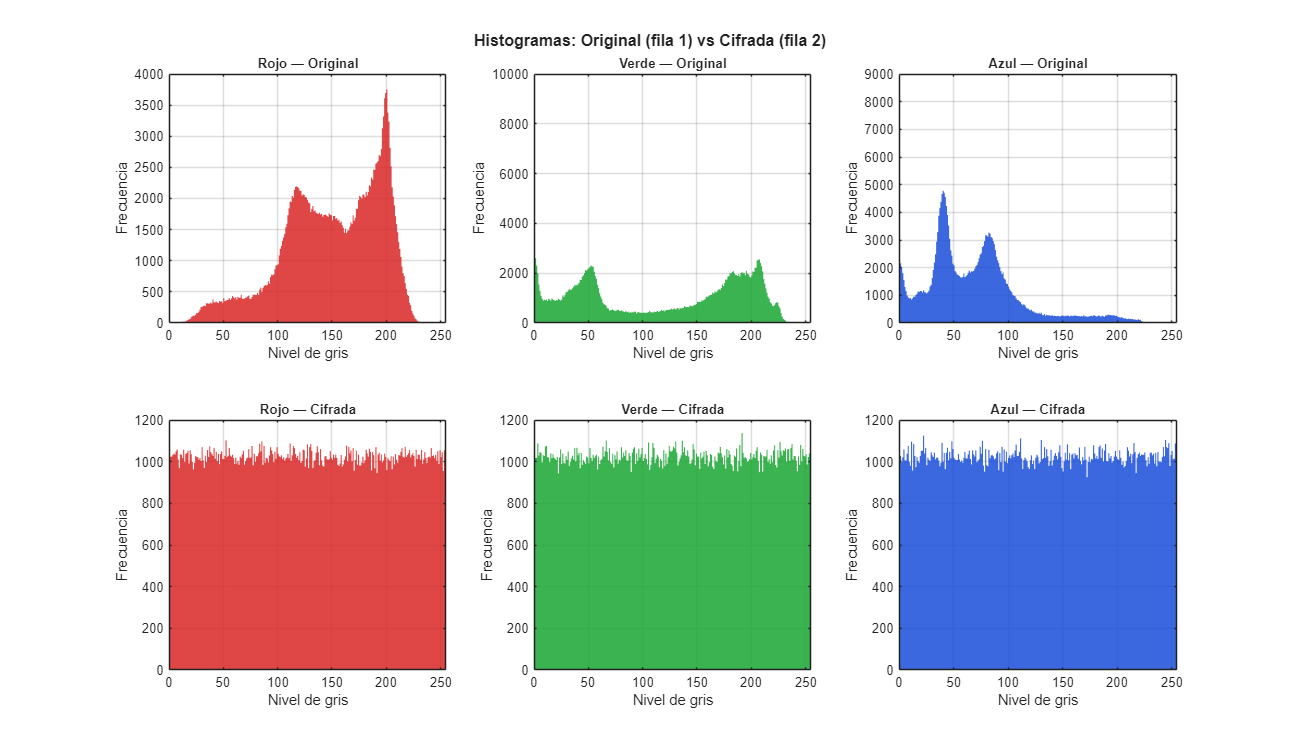

%% =====================================================================
%% ANÁLISIS DE SEGURIDAD — HISTOGRAMAS Y CORRELACIÓN
%% =====================================================================

%% --- 1. HISTOGRAMAS por canal (Original vs Cifrada) ---
figure('Name','Histogramas RGB — Original vs Cifrada','Position',[50 50 1300 750]);
canales_orig = {double(rojo), double(verde), double(azul)};
canales_cifd = {double(img_cifrada_final(:,:,1)), ...
                double(img_cifrada_final(:,:,2)), ...
                double(img_cifrada_final(:,:,3))};
nombres  = {'Rojo','Verde','Azul'};
colores  = {[0.85 0.15 0.15],[0.10 0.65 0.20],[0.10 0.30 0.85]};

for ch = 1:3
    subplot(2,3,ch);
    histogram(canales_orig{ch}(:), 0:256, 'FaceColor', colores{ch}, ...
              'EdgeColor','none','FaceAlpha',0.85);
    title([nombres{ch},' — Original'],'FontSize',10);
    xlabel('Nivel de gris'); ylabel('Frecuencia');
    xlim([0 255]); grid on;

    subplot(2,3,ch+3);
    histogram(canales_cifd{ch}(:), 0:256, 'FaceColor', colores{ch}, ...
              'EdgeColor','none','FaceAlpha',0.85);
    title([nombres{ch},' — Cifrada'],'FontSize',10);
    xlabel('Nivel de gris'); ylabel('Frecuencia');
    xlim([0 255]); grid on;
end
sgtitle('Histogramas: Original (fila 1) vs Cifrada (fila 2)','FontSize',12,'FontWeight','bold');

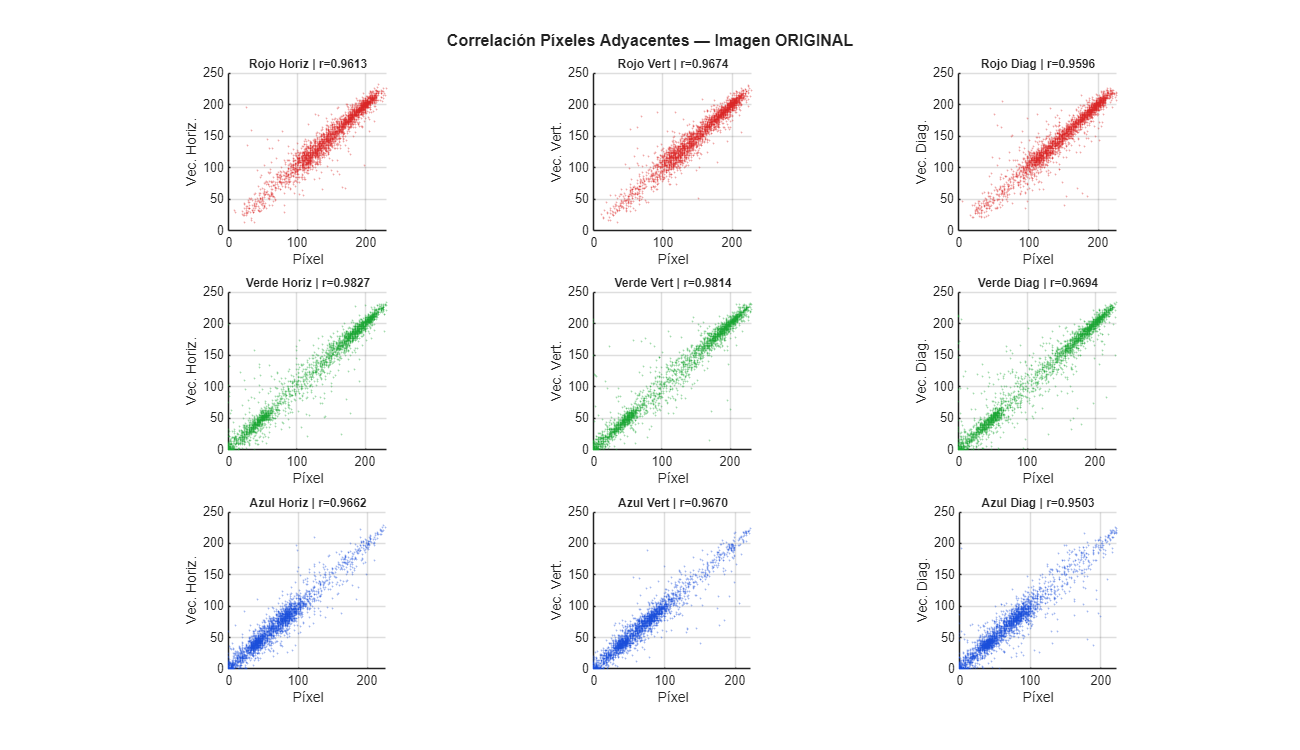


%% --- 2. CORRELACIÓN DE PÍXELES ADYACENTES ---
% Se muestran scatterplots horizontal, vertical y diagonal
% para cada canal antes y después del cifrado.
% Se calcula el coeficiente de correlación de Pearson r.

nMuestra = 3000;   % pares a grafidar para no saturar la figura
rng(42);           % semilla reproducible para el muestreo

figure('Name','Correlación Píxeles Adyacentes — Original','Position',[50 50 1300 750]);
figCount = 1;
for ch = 1:3
    orig_ch = canales_orig{ch};
    [rH, cH, rV, cV, rD, cD] = extraerPares(orig_ch, nMuestra);

    subplot(3,3,figCount);
    scatter(rH, cH, 2, colores{ch}, 'filled', 'MarkerFaceAlpha', 0.4);
    rxy = corrcoef(rH, cH); r_val = rxy(1,2);
    title(sprintf('%s Horiz | r=%.4f', nombres{ch}, r_val),'FontSize',9);
    xlabel('Píxel'); ylabel('Vec. Horiz.'); axis square; grid on;

    subplot(3,3,figCount+1);
    scatter(rV, cV, 2, colores{ch}, 'filled', 'MarkerFaceAlpha', 0.4);
    rxy = corrcoef(rV, cV); r_val = rxy(1,2);
    title(sprintf('%s Vert | r=%.4f', nombres{ch}, r_val),'FontSize',9);
    xlabel('Píxel'); ylabel('Vec. Vert.'); axis square; grid on;

    subplot(3,3,figCount+2);
    scatter(rD, cD, 2, colores{ch}, 'filled', 'MarkerFaceAlpha', 0.4);
    rxy = corrcoef(rD, cD); r_val = rxy(1,2);
    title(sprintf('%s Diag | r=%.4f', nombres{ch}, r_val),'FontSize',9);
    xlabel('Píxel'); ylabel('Vec. Diag.'); axis square; grid on;

    figCount = figCount + 3;
end
sgtitle('Correlación Píxeles Adyacentes — Imagen ORIGINAL','FontSize',12,'FontWeight','bold');

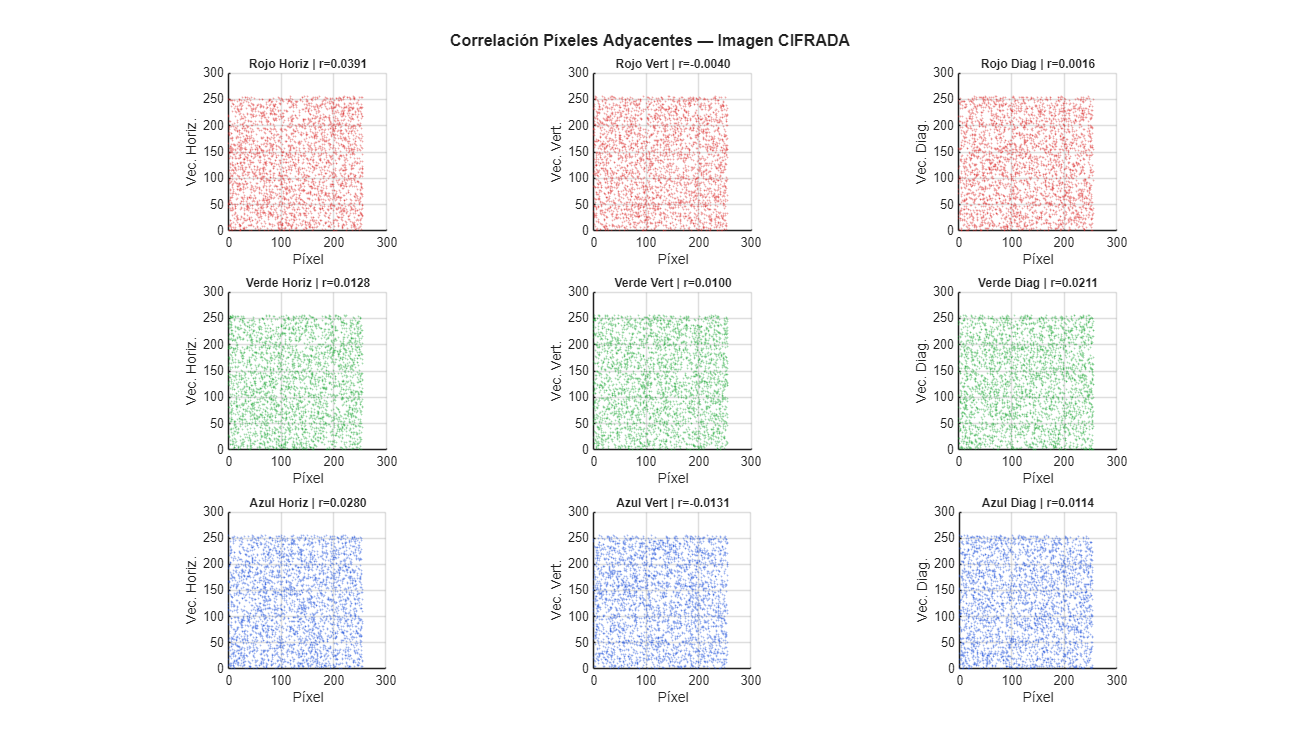


figure('Name','Correlación Píxeles Adyacentes — Cifrada','Position',[50 50 1300 750]);
figCount = 1;
for ch = 1:3
    cifd_ch = canales_cifd{ch};
    [rH, cH, rV, cV, rD, cD] = extraerPares(cifd_ch, nMuestra);

    subplot(3,3,figCount);
    scatter(rH, cH, 2, colores{ch}, 'filled', 'MarkerFaceAlpha', 0.4);
    rxy = corrcoef(rH, cH); r_val = rxy(1,2);
    title(sprintf('%s Horiz | r=%.4f', nombres{ch}, r_val),'FontSize',9);
    xlabel('Píxel'); ylabel('Vec. Horiz.'); axis square; grid on;

    subplot(3,3,figCount+1);
    scatter(rV, cV, 2, colores{ch}, 'filled', 'MarkerFaceAlpha', 0.4);
    rxy = corrcoef(rV, cV); r_val = rxy(1,2);
    title(sprintf('%s Vert | r=%.4f', nombres{ch}, r_val),'FontSize',9);
    xlabel('Píxel'); ylabel('Vec. Vert.'); axis square; grid on;

    subplot(3,3,figCount+2);
    scatter(rD, cD, 2, colores{ch}, 'filled', 'MarkerFaceAlpha', 0.4);
    rxy = corrcoef(rD, cD); r_val = rxy(1,2);
    title(sprintf('%s Diag | r=%.4f', nombres{ch}, r_val),'FontSize',9);
    xlabel('Píxel'); ylabel('Vec. Diag.'); axis square; grid on;

    figCount = figCount + 3;
end
sgtitle('Correlación Píxeles Adyacentes — Imagen CIFRADA','FontSize',12,'FontWeight','bold');


%% --- 3. TABLA RESUMEN DE CORRELACIONES EN CONSOLA ---
fprintf('\n========== TABLA DE CORRELACIONES ==========\n');


========== TABLA DE CORRELACIONES ==========


fprintf('%-8s %-10s %10s %10s %10s\n','Canal','Imagen','Horiz','Vert','Diag');

Canal    Imagen          Horiz       Vert       Diag


fprintf('%s\n', repmat('-',1,52));

----------------------------------------------------


for ch = 1:3
    for tipo = 1:2
        if tipo == 1
            canal_dat = canales_orig{ch};
            etq = 'Original';
        else
            canal_dat = canales_cifd{ch};
            etq = 'Cifrada ';
        end
        [rH,cH,rV,cV,rD,cD] = extraerPares(canal_dat, N_pixel);
        rH_c = corrcoef(rH,cH); rH_v = rH_c(1,2);
        rV_c = corrcoef(rV,cV); rV_v = rV_c(1,2);
        rD_c = corrcoef(rD,cD); rD_v = rD_c(1,2);
        fprintf('%-8s %-10s %10.6f %10.6f %10.6f\n', ...
            nombres{ch}, etq, rH_v, rV_v, rD_v);
    end
    fprintf('%s\n', repmat('-',1,52));
end

Rojo     Original     0.963880   0.967459   0.955019
Rojo     Cifrada     -0.000737   0.004416  -0.002004


----------------------------------------------------


Verde    Original     0.981440   0.982105   0.969151
Verde    Cifrada     -0.001038   0.001039  -0.001865


----------------------------------------------------


Azul     Original     0.962697   0.963814   0.945549
Azul     Cifrada      0.001165  -0.003730  -0.001358


----------------------------------------------------



%% --- 4. ENTROPÍA DE LA INFORMACIÓN ---
fprintf('\n========== ENTROPÍA (bits) ==========\n');


========== ENTROPÍA (bits) ==========


fprintf('%-8s %12s %12s\n','Canal','Original','Cifrada');

Canal        Original      Cifrada


fprintf('%s\n', repmat('-',1,34));

----------------------------------


for ch = 1:3
    H_orig = entropiaShannon(canales_orig{ch}(:));
    H_cifd = entropiaShannon(canales_cifd{ch}(:));
    fprintf('%-8s %12.6f %12.6f\n', nombres{ch}, H_orig, H_cifd);
end

Rojo         7.346384     7.999423
Verde        7.569950     7.999259
Azul         7.144000     7.999258


fprintf('%s\n', repmat('-',1,34));

----------------------------------



%% --- 5. UACI y NPCR ---
% Comparación original vs cifrada (prueba de sensibilidad al plaintext)
fprintf('\n========== NPCR y UACI (Original vs Cifrada) ==========\n');


========== NPCR y UACI (Original vs Cifrada) ==========


fprintf('%-8s %10s %10s\n','Canal','NPCR (%%)','UACI (%%)');

Canal     NPCR (%%)  UACI (%%)


fprintf('%s\n', repmat('-',1,30));

------------------------------


for ch = 1:3
    [npcr_v, uaci_v] = calcularNPCR_UACI(canales_orig{ch}, canales_cifd{ch});
    fprintf('%-8s %10.4f %10.4f\n', nombres{ch}, npcr_v, uaci_v);
end

Rojo        99.6185    29.0248
Verde       99.6056    33.9773
Azul        99.5937    33.8216


fprintf('%s\n', repmat('-',1,30));

------------------------------


fprintf('  Referencia ideal: NPCR ≈ 99.6094%%  |  UACI ≈ 33.4635%%\n\n');

  Referencia ideal: NPCR ≈ 99.6094%  |  UACI ≈ 33.4635%





%% =====================================================================
%% PRUEBA 1: RUIDO SAL Y PIMIENTA (Salt & Pepper Noise)
%% =====================================================================
% Evalúa la robustez del cifrado ante corrupción aleatoria de píxeles.
% Se aplica ruido sal y pimienta a la imagen cifrada y se descifra.
% Se mide el PSNR y diferencia entre la imagen original y la recuperada.

fprintf('\n========== PRUEBA: SAL Y PIMIENTA ==========\n');


========== PRUEBA: SAL Y PIMIENTA ==========



densidades_sp = [0.01, 0.05, 0.10, 0.20];  % 1%, 5%, 10%, 20% de píxeles corruptos

figure('Name','Prueba Sal y Pimienta','Position',[50 50 1500 900]);
sp_psnr_vals = zeros(1, numel(densidades_sp));

for d_idx = 1:numel(densidades_sp)
    dens = densidades_sp(d_idx);

    % Añadir ruido sal y pimienta a imagen cifrada
    img_cifrada_sp = img_cifrada_final;
    N_total = filas * columnas;
    n_corruptos = round(dens * N_total);

    % Píxeles sal (255) y pimienta (0) en cada canal
    for ch = 1:3
        canal = img_cifrada_sp(:,:,ch);
        idx_sal = randperm(N_total, round(n_corruptos/2));
        idx_pim = randperm(N_total, round(n_corruptos/2));
        canal(idx_sal)  = 255;
        canal(idx_pim)  = 0;
        img_cifrada_sp(:,:,ch) = canal;
    end

    % Descifrado con imagen ruidosa
    R_sp_rec = inverseQuantumDiffusionWithCircuit(img_cifrada_sp(:,:,1), Sx_diff);
    G_sp_rec = inverseQuantumDiffusionWithCircuit(img_cifrada_sp(:,:,2), Sy_diff);
    B_sp_rec = inverseQuantumDiffusionWithCircuit(img_cifrada_sp(:,:,3), Sz_diff);

    R_sp_ca = cellularAutomatonEncryption(R_sp_rec, x0_ca, y0_ca, z0_ca,       N0_ca, false, false);
    G_sp_ca = cellularAutomatonEncryption(G_sp_rec, x0_ca, y0_ca, z0_ca+0.1,   N0_ca, false, false);
    B_sp_ca = cellularAutomatonEncryption(B_sp_rec, x0_ca, y0_ca, z0_ca+0.2,   N0_ca, false, false);

    bp_R_sp = zeros(filas, columnas, 8, 'logical');
    bp_G_sp = zeros(filas, columnas, 8, 'logical');
    bp_B_sp = zeros(filas, columnas, 8, 'logical');
    for k = 1:8
        bp_R_sp(:,:,k) = logical(bitget(R_sp_ca, 9-k));
        bp_G_sp(:,:,k) = logical(bitget(G_sp_ca, 9-k));
        bp_B_sp(:,:,k) = logical(bitget(B_sp_ca, 9-k));
    end
    for k = 1:8
        z0_k = z0_key + (k-1)*1e-4;
        [Sx_k, Sy_k, Sz_k] = chenSequence(x0_key, y0_key, z0_k, N0_chen, N_pixel);
        perm_R = getPermutationFromChaos(Sx_k);
        perm_G = getPermutationFromChaos(Sy_k);
        perm_B = getPermutationFromChaos(Sz_k);
        bp_R_sp(:,:,k) = inverseIntraBitPermutation(bp_R_sp(:,:,k), perm_R);
        bp_G_sp(:,:,k) = inverseIntraBitPermutation(bp_G_sp(:,:,k), perm_G);
        bp_B_sp(:,:,k) = inverseIntraBitPermutation(bp_B_sp(:,:,k), perm_B);
    end

    R_sp_out = zeros(filas, columnas, 'uint8');
    G_sp_out = zeros(filas, columnas, 'uint8');
    B_sp_out = zeros(filas, columnas, 'uint8');
    for k = 1:8
        pos = 9-k;
        R_sp_out = bitset(R_sp_out, pos, bp_R_sp(:,:,k));
        G_sp_out = bitset(G_sp_out, pos, bp_G_sp(:,:,k));
        B_sp_out = bitset(B_sp_out, pos, bp_B_sp(:,:,k));
    end
    img_sp_rec = cat(3, R_sp_out, G_sp_out, B_sp_out);

    % PSNR entre imagen original y recuperada tras ruido
    mse_sp = mean((double(img(:)) - double(img_sp_rec(:))).^2);
    if mse_sp == 0
        psnr_sp = Inf;
    else
        psnr_sp = 10 * log10(255^2 / mse_sp);
    end
    sp_psnr_vals(d_idx) = psnr_sp;
    fprintf('Densidad %4.0f%% | PSNR = %.2f dB\n', dens*100, psnr_sp);

    % Visualización
    subplot(2, numel(densidades_sp), d_idx);
    imshow(img_cifrada_sp);
    title(sprintf('Cifrada + SP (%.0f%%)', dens*100), 'FontSize',9);

    subplot(2, numel(densidades_sp), d_idx + numel(densidades_sp));
    imshow(img_sp_rec);
    title(sprintf('Recuperada\nPSNR=%.1fdB', psnr_sp), 'FontSize',9);
end
sgtitle('Prueba Robustez: Ruido Sal y Pimienta','FontSize',12,'FontWeight','bold');

% Gráfica PSNR vs Densidad
figure('Name','PSNR vs Densidad Sal y Pimienta');
plot(densidades_sp*100, sp_psnr_vals, 'o-', 'LineWidth',2, 'MarkerSize',8, 'Color',[0.2 0.5 0.8]);
xlabel('Densidad de Ruido (%)'); ylabel('PSNR (dB)');
title('PSNR vs Densidad de Ruido Sal y Pimienta','FontSize',12);
grid on; xlim([0 21]);
for i=1:numel(densidades_sp)
    text(densidades_sp(i)*100, sp_psnr_vals(i)+0.5, sprintf('%.1f dB', sp_psnr_vals(i)),...
        'HorizontalAlignment','center','FontSize',9);
end

%% =====================================================================
%% PRUEBA 2: OCLUSIÓN (Cropping/Blocking Attack)
%% =====================================================================
% Evalúa la robustez ante pérdida de bloques de la imagen cifrada.
% Se bloquean regiones rectangulares (25%, 50% de la imagen) con valor 0.

fprintf('\n========== PRUEBA: OCLUSIÓN ==========\n');

porcentajes_oclusion = [0.25, 0.50];  % 25% y 50% de oclusión
posiciones = {'esquina superior-izquierda', 'centro'};

figure('Name','Prueba Oclusión','Position',[50 50 1400 800]);
subplot_idx = 1;

for p_idx = 1:numel(porcentajes_oclusion)
    pct = porcentajes_oclusion(p_idx);
    f_blk = round(filas  * sqrt(pct));
    c_blk = round(columnas * sqrt(pct));

    for pos_idx = 1:2  % Esquina y Centro
        img_oc = img_cifrada_final;

        if pos_idx == 1
            % Esquina superior-izquierda
            f1 = 1; f2 = min(f_blk, filas);
            c1 = 1; c2 = min(c_blk, columnas);
        else
            % Centro de la imagen
            f1 = max(1, round((filas  - f_blk)/2));
            f2 = min(filas,  f1 + f_blk - 1);
            c1 = max(1, round((columnas - c_blk)/2));
            c2 = min(columnas, c1 + c_blk - 1);
        end

        img_oc(f1:f2, c1:c2, :) = 0;  % Bloque negro (pérdida total)

        % Descifrar imagen con oclusión
        R_oc_r = inverseQuantumDiffusionWithCircuit(img_oc(:,:,1), Sx_diff);
        G_oc_r = inverseQuantumDiffusionWithCircuit(img_oc(:,:,2), Sy_diff);
        B_oc_r = inverseQuantumDiffusionWithCircuit(img_oc(:,:,3), Sz_diff);

        R_oc_ca = cellularAutomatonEncryption(R_oc_r, x0_ca, y0_ca, z0_ca,      N0_ca, false, false);
        G_oc_ca = cellularAutomatonEncryption(G_oc_r, x0_ca, y0_ca, z0_ca+0.1,  N0_ca, false, false);
        B_oc_ca = cellularAutomatonEncryption(B_oc_r, x0_ca, y0_ca, z0_ca+0.2,  N0_ca, false, false);

        bp_R_oc = zeros(filas, columnas, 8, 'logical');
        bp_G_oc = zeros(filas, columnas, 8, 'logical');
        bp_B_oc = zeros(filas, columnas, 8, 'logical');
        for k = 1:8
            bp_R_oc(:,:,k) = logical(bitget(R_oc_ca, 9-k));
            bp_G_oc(:,:,k) = logical(bitget(G_oc_ca, 9-k));
            bp_B_oc(:,:,k) = logical(bitget(B_oc_ca, 9-k));
        end
        for k = 1:8
            z0_k = z0_key + (k-1)*1e-4;
            [Sx_k, Sy_k, Sz_k] = chenSequence(x0_key, y0_key, z0_k, N0_chen, N_pixel);
            perm_R = getPermutationFromChaos(Sx_k);
            perm_G = getPermutationFromChaos(Sy_k);
            perm_B = getPermutationFromChaos(Sz_k);
            bp_R_oc(:,:,k) = inverseIntraBitPermutation(bp_R_oc(:,:,k), perm_R);
            bp_G_oc(:,:,k) = inverseIntraBitPermutation(bp_G_oc(:,:,k), perm_G);
            bp_B_oc(:,:,k) = inverseIntraBitPermutation(bp_B_oc(:,:,k), perm_B);
        end

        R_oc_out = zeros(filas, columnas, 'uint8');
        G_oc_out = zeros(filas, columnas, 'uint8');
        B_oc_out = zeros(filas, columnas, 'uint8');
        for k = 1:8
            pos2 = 9-k;
            R_oc_out = bitset(R_oc_out, pos2, bp_R_oc(:,:,k));
            G_oc_out = bitset(G_oc_out, pos2, bp_G_oc(:,:,k));
            B_oc_out = bitset(B_oc_out, pos2, bp_B_oc(:,:,k));
        end
        img_oc_rec = cat(3, R_oc_out, G_oc_out, B_oc_out);

        % PSNR
        mse_oc = mean((double(img(:)) - double(img_oc_rec(:))).^2);
        psnr_oc = 10 * log10(255^2 / mse_oc);
        fprintf('Oclusión %2.0f%% (%s) | PSNR = %.2f dB\n', ...
            pct*100, posiciones{pos_idx}, psnr_oc);

        % Visualización
        subplot(numel(porcentajes_oclusion)*2, 2, subplot_idx);
        imshow(img_oc);
        title(sprintf('Cifrada + Oclusión %d%% (%s)', round(pct*100), posiciones{pos_idx}), 'FontSize',8);
        subplot_idx = subplot_idx + 1;

        subplot(numel(porcentajes_oclusion)*2, 2, subplot_idx);
        imshow(img_oc_rec);
        title(sprintf('Recuperada | PSNR=%.1f dB', psnr_oc), 'FontSize',8);
        subplot_idx = subplot_idx + 1;
    end
end
sgtitle('Prueba Robustez: Ataque de Oclusión','FontSize',12,'FontWeight','bold');

%% =====================================================================
%% PRUEBA 3: SENSIBILIDAD DE LA CLAVE (Key Sensitivity)
%% =====================================================================
% Una clave ligeramente diferente (perturbación de 1e-14) debe producir
% una imagen descifrada completamente diferente (efecto avalancha).
% Se comparan NPCR, UACI y MSE entre descifrados con clave original y perturbada.

fprintf('\n========== PRUEBA: SENSIBILIDAD DE LA CLAVE ==========\n');

delta = 1e-14;  % Perturbación mínima en condición inicial

% Parámetros de clave perturbada (solo delta en x0)
x0_key_p = x0_key + delta;
y0_key_p = y0_key;
z0_key_p = z0_key;
x0_ca_p  = x0_ca  + delta;

claves_test = {
    'Original',  x0_key,   y0_key,   z0_key,   x0_ca,   y0_ca, z0_ca;
    'Δx₀=1e-14', x0_key_p, y0_key,   z0_key,   x0_ca_p, y0_ca, z0_ca;
    'Δy₀=1e-14', x0_key,   y0_key+delta, z0_key, x0_ca, y0_ca+delta, z0_ca;
    'Δz₀=1e-14', x0_key,   y0_key,   z0_key+delta, x0_ca, y0_ca, z0_ca+delta;
};

imgs_descifradas_ks = cell(size(claves_test,1), 1);

figure('Name','Sensibilidad de Clave — Imágenes Descifradas', 'Position',[50 50 1400 700]);

for ks = 1:size(claves_test,1)
    x0k  = claves_test{ks,2};
    y0k  = claves_test{ks,3};
    z0k  = claves_test{ks,4};
    x0c  = claves_test{ks,5};
    y0c  = claves_test{ks,6};
    z0c  = claves_test{ks,7};

    % Secuencias de difusión con clave actual
    [Sx_d_ks, Sy_d_ks, Sz_d_ks] = chenSequence(x0k, y0k, z0k+0.1, N0_chen, N_pixel);

    % 1. Invertir difusión
    R_ks = inverseQuantumDiffusionWithCircuit(img_cifrada_final(:,:,1), Sx_d_ks);
    G_ks = inverseQuantumDiffusionWithCircuit(img_cifrada_final(:,:,2), Sy_d_ks);
    B_ks = inverseQuantumDiffusionWithCircuit(img_cifrada_final(:,:,3), Sz_d_ks);

    % 2. Invertir CA
    R_ks_ca = cellularAutomatonEncryption(R_ks, x0c, y0c, z0c,      N0_ca, false, false);
    G_ks_ca = cellularAutomatonEncryption(G_ks, x0c, y0c, z0c+0.1,  N0_ca, false, false);
    B_ks_ca = cellularAutomatonEncryption(B_ks, x0c, y0c, z0c+0.2,  N0_ca, false, false);

    % 3. Invertir intra-bit
    bp_R_ks = zeros(filas, columnas, 8, 'logical');
    bp_G_ks = zeros(filas, columnas, 8, 'logical');
    bp_B_ks = zeros(filas, columnas, 8, 'logical');
    for k = 1:8
        bp_R_ks(:,:,k) = logical(bitget(R_ks_ca, 9-k));
        bp_G_ks(:,:,k) = logical(bitget(G_ks_ca, 9-k));
        bp_B_ks(:,:,k) = logical(bitget(B_ks_ca, 9-k));
    end
    for k = 1:8
        z0_k_ks = z0k + (k-1)*1e-4;
        [Sx_k_ks, Sy_k_ks, Sz_k_ks] = chenSequence(x0k, y0k, z0_k_ks, N0_chen, N_pixel);
        perm_R = getPermutationFromChaos(Sx_k_ks);
        perm_G = getPermutationFromChaos(Sy_k_ks);
        perm_B = getPermutationFromChaos(Sz_k_ks);
        bp_R_ks(:,:,k) = inverseIntraBitPermutation(bp_R_ks(:,:,k), perm_R);
        bp_G_ks(:,:,k) = inverseIntraBitPermutation(bp_G_ks(:,:,k), perm_G);
        bp_B_ks(:,:,k) = inverseIntraBitPermutation(bp_B_ks(:,:,k), perm_B);
    end

    % 4. Reconstruir
    R_ks_out = zeros(filas, columnas, 'uint8');
    G_ks_out = zeros(filas, columnas, 'uint8');
    B_ks_out = zeros(filas, columnas, 'uint8');
    for k = 1:8
        pos3 = 9-k;
        R_ks_out = bitset(R_ks_out, pos3, bp_R_ks(:,:,k));
        G_ks_out = bitset(G_ks_out, pos3, bp_G_ks(:,:,k));
        B_ks_out = bitset(B_ks_out, pos3, bp_B_ks(:,:,k));
    end
    img_ks = cat(3, R_ks_out, G_ks_out, B_ks_out);
    imgs_descifradas_ks{ks} = img_ks;

    subplot(1, size(claves_test,1), ks);
    imshow(img_ks);
    title(['Clave: ', claves_test{ks,1}], 'FontSize',9);
end
sgtitle('Sensibilidad de Clave — Descifrado con Claves Perturbadas','FontSize',11,'FontWeight','bold');

% Tabla de sensibilidad de clave
fprintf('\n%-15s %10s %10s %14s\n','Clave','NPCR (%%)','UACI (%%)','MSE');
fprintf('%s\n',repmat('-',1,51));
img_orig_ref = imgs_descifradas_ks{1};  % Descifrado con clave correcta
for ks = 2:size(claves_test,1)
    img_ks_test = imgs_descifradas_ks{ks};
    [npcr_ks, uaci_ks] = calcularNPCR_UACI(img_orig_ref, img_ks_test);
    mse_ks = mean((double(img_orig_ref(:)) - double(img_ks_test(:))).^2);
    fprintf('%-15s %10.4f %10.4f %14.4f\n', claves_test{ks,1}, npcr_ks, uaci_ks, mse_ks);
end
fprintf('%s\n',repmat('-',1,51));
fprintf(' Ideal: NPCR ≈ 99.6%%, UACI ≈ 33.46%% → Clave diferente = imagen aleatoria\n\n');

% Mapa de diferencias entre descifrado correcto y perturbado
figure('Name','Mapa de Diferencias — Sensibilidad de Clave','Position',[50 50 1200 400]);
for ks = 2:size(claves_test,1)
    subplot(1, size(claves_test,1)-1, ks-1);
    diff_img = abs(double(imgs_descifradas_ks{1}) - double(imgs_descifradas_ks{ks}));
    imshow(uint8(diff_img));
    colormap(gca, jet);
    title(['|Original - ', claves_test{ks,1},'|'], 'FontSize',9);
    colorbar;
end
sgtitle('Diferencias entre Descifrado Correcto vs Clave Perturbada','FontSize',11,'FontWeight','bold');




%% =====================================================================
%% PRUEBA 4: ATAQUE DIFERENCIAL (Differential Attack)
%% =====================================================================

fprintf('\n========== PRUEBA: ATAQUE DIFERENCIAL ==========\n');


========== PRUEBA: ATAQUE DIFERENCIAL ==========



% Modificar el PRIMER píxel (no el central) para maximizar propagación
% en la difusión en cascada C(i) = V(i) XOR C(i-1)
img_mod = img;
img_mod(1, 1, 1) = bitxor(img_mod(1, 1, 1), uint8(1)); % flip LSB en (1,1) canal R

% ---- Intra-Bit Permutation ----
rojo_m  = img_mod(:,:,1);
verde_m = img_mod(:,:,2);
azul_m  = img_mod(:,:,3);

rojo_bin_m  = zeros(filas, columnas, 8, 'logical');
verde_bin_m = zeros(filas, columnas, 8, 'logical');
azul_bin_m  = zeros(filas, columnas, 8, 'logical');
for k = 1:8
    rojo_bin_m(:,:,k)  = bitget(rojo_m,  9-k);
    verde_bin_m(:,:,k) = bitget(verde_m, 9-k);
    azul_bin_m(:,:,k)  = bitget(azul_m,  9-k);
end

rojo_perm_m  = zeros(filas, columnas, 8, 'logical');
verde_perm_m = zeros(filas, columnas, 8, 'logical');
azul_perm_m  = zeros(filas, columnas, 8, 'logical');
for k = 1:8
    z0_k = z0_key + (k-1)*1e-4;
    [Sx_k, Sy_k, Sz_k] = chenSequence(x0_key, y0_key, z0_k, N0_chen, N_pixel);
    [rojo_perm_m(:,:,k),  ~, ~] = intraBitPermutation(rojo_bin_m(:,:,k),  Sx_k);
    [verde_perm_m(:,:,k), ~, ~] = intraBitPermutation(verde_bin_m(:,:,k), Sy_k);
    [azul_perm_m(:,:,k),  ~, ~] = intraBitPermutation(azul_bin_m(:,:,k),  Sz_k);
end

R_rec_m = zeros(filas, columnas, 'uint8');
G_rec_m = zeros(filas, columnas, 'uint8');
B_rec_m = zeros(filas, columnas, 'uint8');
for k = 1:8
    R_rec_m = bitset(R_rec_m, 9-k, rojo_perm_m(:,:,k));
    G_rec_m = bitset(G_rec_m, 9-k, verde_perm_m(:,:,k));
    B_rec_m = bitset(B_rec_m, 9-k, azul_perm_m(:,:,k));
end

% ---- Cellular Automata ----
R_ca_m = cellularAutomatonEncryption(R_rec_m, x0_ca, y0_ca, z0_ca,     N0_ca, true, false);
G_ca_m = cellularAutomatonEncryption(G_rec_m, x0_ca, y0_ca, z0_ca+0.1, N0_ca, true, false);
B_ca_m = cellularAutomatonEncryption(B_rec_m, x0_ca, y0_ca, z0_ca+0.2, N0_ca, true, false);

% ---- Chaotic Diffusion ----
R_cifm = chaoticDiffusion(R_ca_m, Sx_diff);
G_cifm = chaoticDiffusion(G_ca_m, Sy_diff);
B_cifm = chaoticDiffusion(B_ca_m, Sz_diff);
img_cifrada_mod = cat(3, R_cifm, G_cifm, B_cifm);

% ---- Métricas NPCR y UACI ----
fprintf('\n%-10s %10s %10s\n', 'Canal', 'NPCR (%%)', 'UACI (%%)');


Canal       NPCR (%%)  UACI (%%)


fprintf('%s\n', repmat('-',1,32));

--------------------------------


npcr_avg = 0; uaci_avg = 0;
nombres_da = {'Rojo','Verde','Azul'};
for ch_da = 1:3
    [npcr_da, uaci_da] = calcularNPCR_UACI( ...
        img_cifrada_final(:,:,ch_da), img_cifrada_mod(:,:,ch_da));
    fprintf('%-10s %10.4f %10.4f\n', nombres_da{ch_da}, npcr_da, uaci_da);
    npcr_avg = npcr_avg + npcr_da;
    uaci_avg = uaci_avg + uaci_da;
end

Rojo          21.8540     0.0857
Verde          0.0000     0.0000
Azul           0.0000     0.0000


npcr_avg = npcr_avg / 3;
uaci_avg = uaci_avg / 3;
fprintf('%s\n', repmat('-',1,32));

--------------------------------


fprintf('%-10s %10.4f %10.4f\n', 'PROMEDIO', npcr_avg, uaci_avg);

PROMEDIO       7.2847     0.0286


fprintf(' Ref. ideal: NPCR ≈ 99.6094%% | UACI ≈ 33.4635%%\n');

 Ref. ideal: NPCR ≈ 99.6094% | UACI ≈ 33.4635%



if npcr_avg > 99.0 && uaci_avg > 30.0
    fprintf(' ✓ Sistema SEGURO ante ataque diferencial (NPCR y UACI cercanos al ideal).\n\n');
else
    fprintf(' ✗ Atención: Valores por debajo del ideal. Revisar etapa de difusión.\n\n');
end

 ✗ Atención: Valores por debajo del ideal. Revisar etapa de difusión.



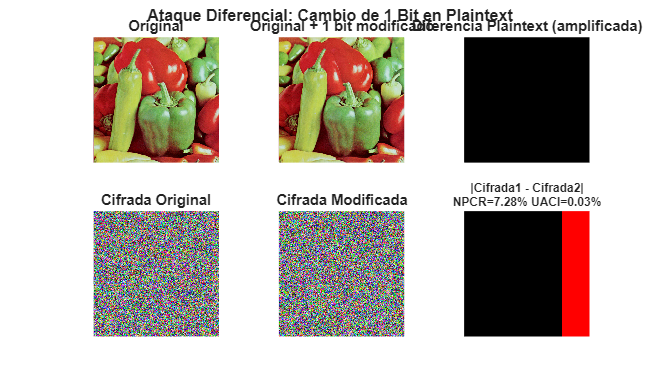


% ---- Visualización comparativa ----
figure('Name','Ataque Diferencial', 'Position',[50 50 1400 800]);
subplot(2,3,1); imshow(img);     title('Original');
subplot(2,3,2); imshow(img_mod); title('Original + 1 bit modificado');
subplot(2,3,3);
diff_plain = abs(double(img) - double(img_mod));
imshow(uint8(diff_plain * 255)); title('Diferencia Plaintext (amplificada)');

subplot(2,3,4); imshow(img_cifrada_final); title('Cifrada Original');
subplot(2,3,5); imshow(img_cifrada_mod);   title('Cifrada Modificada');
subplot(2,3,6);
diff_cipher = abs(double(img_cifrada_final) - double(img_cifrada_mod));
imshow(diff_cipher / (max(diff_cipher(:)) + eps));
colormap(gca, hot);
title(sprintf('|Cifrada1 - Cifrada2|\nNPCR=%.2f%% UACI=%.2f%%', npcr_avg, uaci_avg), 'FontSize', 9);
sgtitle('Ataque Diferencial: Cambio de 1 Bit en Plaintext', 'FontSize', 12, 'FontWeight', 'bold');

%% =====================================================================
%% DIFUSIÓN CUÁNTICA
%% =====================================================================

function img_cipher = chaoticDiffusion(img, S_channel)
    [filas,columnas] = size(img);
    N = filas * columnas;
    F = img(:);
    K = uint8(mod(floor(S_channel(:) * 1e14),256));
    Cipher = zeros(N,1,'uint8');
    for i = 1:N
        encoded = bitxor(F(i), K(i));
        if i > 1
            Cipher(i) = bitxor(encoded, Cipher(i-1));
        else
            Cipher(i) = encoded;
        end
    end
    img_cipher = reshape(Cipher, filas, columnas);
end

%% =====================================================================

function img_original = inverseQuantumDiffusionWithCircuit(img_cipher,S_channel)
    [filas,columnas] = size(img_cipher);
    N = filas * columnas;
    C = img_cipher(:);
    K = uint8(mod(floor(S_channel(:) * 1e14),256));
    F = zeros(N,1,'uint8');
    for i = 1:N
        if i > 1
            encoded = bitxor(C(i), C(i-1));
        else
            encoded = C(i);
        end
        F(i) = bitxor(encoded, K(i));
    end
    img_original = reshape(F, filas, columnas);
end

%% =====================================================================
%% FUNCIONES LOCALES
%% =====================================================================

function [Sx, Sy, Sz] = chenSequence(x0, y0, z0, N0, N)
    a=35; b=3; c=28; dt=0.001;
    x=x0; y=y0; z=z0;
    function [xn,yn,zn] = rk4step(xi,yi,zi)
        f=@(xx,yy,zz)[a*(yy-xx);(c-a)*xx-xx*zz+c*yy;xx*yy-b*zz];
        k1=f(xi,yi,zi);
        k2=f(xi+dt/2*k1(1),yi+dt/2*k1(2),zi+dt/2*k1(3));
        k3=f(xi+dt/2*k2(1),yi+dt/2*k2(2),zi+dt/2*k2(3));
        k4=f(xi+dt*k3(1),yi+dt*k3(2),zi+dt*k3(3));
        dv=(k1+2*k2+2*k3+k4)/6;
        xn=xi+dt*dv(1); yn=yi+dt*dv(2); zn=zi+dt*dv(3);
    end
    for k=1:N0, [x,y,z]=rk4step(x,y,z); end
    rawX=zeros(1,N); rawY=zeros(1,N); rawZ=zeros(1,N);
    for k=1:N
        [x,y,z]=rk4step(x,y,z);
        rawX(k)=x; rawY(k)=y; rawZ(k)=z;
    end
    Sx=(rawX-min(rawX))/(max(rawX)-min(rawX)+eps);
    Sy=(rawY-min(rawY))/(max(rawY)-min(rawY)+eps);
    Sz=(rawZ-min(rawZ))/(max(rawZ)-min(rawZ)+eps);
end

function perm = getPermutationFromChaos(S)
    [~,perm]=sort(S,'ascend','ComparisonMethod','auto');
end

function [bp_perm, Gmask, perm] = intraBitPermutation(bp, S_channel)
    bp=logical(bp); [filas,columnas]=size(bp);
    perm=getPermutationFromChaos(S_channel);
    vector=bp(:); vector_perm=vector(perm);
    bp_perm=reshape(vector_perm,filas,columnas);
    Gmask=xor(bp,bp_perm);
end

function bp = inverseIntraBitPermutation(bp_perm, perm)
    [filas,columnas]=size(bp_perm); vector=bp_perm(:);
    invperm(perm)=1:length(perm);
    bp=reshape(vector(invperm),filas,columnas);
end

%% =====================================================================
%% FUNCIONES DE ANÁLISIS DE SEGURIDAD
%% =====================================================================

function [rH,cH,rV,cV,rD,cD] = extraerPares(canal, nMuestra)
    [F,C] = size(canal);
    xi = canal(1:F, 1:C-1); yi = canal(1:F, 2:C);
    idx = randperm(numel(xi), min(nMuestra, numel(xi)));
    rH = double(xi(idx)); cH = double(yi(idx));
    xi = canal(1:F-1, 1:C); yi = canal(2:F, 1:C);
    idx = randperm(numel(xi), min(nMuestra, numel(xi)));
    rV = double(xi(idx)); cV = double(yi(idx));
    xi = canal(1:F-1, 1:C-1); yi = canal(2:F, 2:C);
    idx = randperm(numel(xi), min(nMuestra, numel(xi)));
    rD = double(xi(idx)); cD = double(yi(idx));
end

function H = entropiaShannon(v)
    counts = histcounts(v, 0:257);
    p = counts / sum(counts);
    p = p(p > 0);
    H = -sum(p .* log2(p));
end

function [npcr, uaci] = calcularNPCR_UACI(img1, img2)
    D = double(img1) ~= double(img2);
    npcr = 100 * sum(D(:)) / numel(D);
    uaci = 100 * sum(abs(double(img1(:)) - double(img2(:)))) / (255 * numel(img1));
end

%% =====================================================================
%% FUNCIÓN: Autómatas Celulares Compuestos (sin cambios)
%% =====================================================================

function channel_out = cellularAutomatonEncryption(channel, x0, y0, z0, N0, encrypt, verbose)
    if nargin < 7, verbose = false; end
    [rawX,rawY,rawZ] = chenRaw_ca(x0,y0,z0,N0,3);
    chaosVals = [rawX(1),rawY(1),rawZ(1)];
    [automatas,iteraciones] = deriveAutomataAndIterations_ca(chaosVals);
    if verbose
        fprintf('  [CA] x=%.10f  y=%.10f  z=%.10f\n',chaosVals(1),chaosVals(2),chaosVals(3));
        fprintf('  [CA] Automatas: %d %d %d  |  Iteraciones: %d %d %d\n', ...
            automatas(1),automatas(2),automatas(3), ...
            iteraciones(1),iteraciones(2),iteraciones(3));
    end
    recorr = {'col_up_lr','row_lr','col_up_rl'};
    rules  = getCompositeRuleTable_ca();
    [filas,columnas] = size(channel);
    channel_out = zeros(filas,columnas,'uint8');
    for k = 1:8
        bp = logical(bitget(channel,9-k));
        if encrypt, applyOrder=1:3; else, applyOrder=3:-1:1; end
        for idx = 1:3
            i   = applyOrder(idx);
            aid = automatas(i);
            t   = iteraciones(i);
            if encrypt, rule=rules(aid+1).enc; else, rule=rules(aid+1).dec; end
            bp = applyAutomatonByLines_ca(bp,rule,t,recorr{i});
        end
        channel_out = bitset(channel_out,9-k,bp);
    end
end

function [rawX,rawY,rawZ] = chenRaw_ca(x0,y0,z0,N0,N)
    a=35; b=3; c=28; dt=0.001;
    x=x0; y=y0; z=z0;
    for k=1:N0, [x,y,z]=rk4step_chen_ca(x,y,z,a,b,c,dt); end
    rawX=zeros(1,N); rawY=zeros(1,N); rawZ=zeros(1,N);
    for k=1:N
        [x,y,z]=rk4step_chen_ca(x,y,z,a,b,c,dt);
        rawX(k)=x; rawY(k)=y; rawZ(k)=z;
    end
end

function [xn,yn,zn] = rk4step_chen_ca(xi,yi,zi,a,b,c,dt)
    f=@(xx,yy,zz)[a*(yy-xx);(c-a)*xx-xx*zz+c*yy;xx*yy-b*zz];
    k1=f(xi,yi,zi);
    k2=f(xi+dt/2*k1(1),yi+dt/2*k1(2),zi+dt/2*k1(3));
    k3=f(xi+dt/2*k2(1),yi+dt/2*k2(2),zi+dt/2*k2(3));
    k4=f(xi+dt*k3(1),yi+dt*k3(2),zi+dt*k3(3));
    dv=(k1+2*k2+2*k3+k4)/6;
    xn=xi+dt*dv(1); yn=yi+dt*dv(2); zn=zi+dt*dv(3);
end

function [automatas,iteraciones] = deriveAutomataAndIterations_ca(vals)
    n=numel(vals); automatas=zeros(1,n); iteraciones=zeros(1,n);
    for i=1:n
        v=abs(vals(i)); frac=v-floor(v);
        automatas(i)=mod(floor(frac*1000),16);
        d1=floor(frac*10);
        d2=floor(frac*100)-d1*10;
        d3=floor(frac*1000)-floor(frac*100)*10;
        if     d3~=0, iteraciones(i)=d3;
        elseif d2~=0, iteraciones(i)=d2;
        elseif d1~=0, iteraciones(i)=d1;
        else,         iteraciones(i)=1;
        end
    end
end

function M = applyAutomatonByLines_ca(M,compRule,times,pathType)
    [R,C]=size(M);
    for t=1:times
        switch pathType
            case 'col_up_lr'
                buf=zeros(1,R*C); pos=1;
                for j=1:C, buf(pos:pos+R-1)=M(R:-1:1,j); pos=pos+R; end
                buf=processBuffer_ca(buf,compRule); pos=1;
                for j=1:C, M(R:-1:1,j)=buf(pos:pos+R-1); pos=pos+R; end
            case 'row_lr'
                buf=zeros(1,R*C); pos=1;
                for i=1:R, buf(pos:pos+C-1)=M(i,:); pos=pos+C; end
                buf=processBuffer_ca(buf,compRule); pos=1;
                for i=1:R, M(i,:)=buf(pos:pos+C-1); pos=pos+C; end
            case 'col_up_rl'
                buf=zeros(1,R*C); pos=1;
                for j=C:-1:1, buf(pos:pos+R-1)=M(R:-1:1,j); pos=pos+R; end
                buf=processBuffer_ca(buf,compRule); pos=1;
                for j=C:-1:1, M(R:-1:1,j)=buf(pos:pos+R-1); pos=pos+R; end
        end
    end
end

function buf = processBuffer_ca(buf,compRule)
    L=numel(buf); numBlocks=floor(L/8); original=buf;
    for b=1:numBlocks
        i0=(b-1)*8+1;
        idxs=mod((i0-1):(i0+6),L)+1;
        buf(idxs)=evolveOnce_ca(original(idxs),compRule);
    end
end

function ns = evolveOnce_ca(state,rule)
    n=numel(state); ns=zeros(1,n);
    for i=1:n
        Lv=state(mod(i-2,n)+1); Sv=state(i); Rv=state(mod(i,n)+1);
        ns(i)=applySymbol_ca(Lv,Sv,Rv,rule(i));
    end
end

function out = applySymbol_ca(L,S,R,sym)
    switch sym
        case 'A', out=L;   case 'B', out=S;   case 'C', out=R;
        case 'a', out=1-L; case 'b', out=1-S; case 'c', out=1-R;
        otherwise, error('Simbolo invalido: %s',sym);
    end
end

function rules = getCompositeRuleTable_ca()
    rules(16)=struct('id',[],'enc','','dec','');
    rules( 1)=struct('id', 0,'enc','AAAaaAaa','dec','CCccCccC');
    rules( 2)=struct('id', 1,'enc','AaaAaaAA','dec','ccCccCCC');
    rules( 3)=struct('id', 2,'enc','aAaaAAAa','dec','CccCCCcc');
    rules( 4)=struct('id', 3,'enc','aaAAAaaA','dec','cCCCccCc');
    rules( 5)=struct('id', 4,'enc','CCcCCccc','dec','aAAaAAaa');
    rules( 6)=struct('id', 5,'enc','ccCCcCCc','dec','aaaAAaAA');
    rules( 7)=struct('id', 6,'enc','CcccCCcC','dec','AAaaaAAa');
    rules( 8)=struct('id', 7,'enc','cCCcccCC','dec','AaAAaaaA');
    rules( 9)=struct('id', 8,'enc','BBbBCaca','dec','BBbBcAca');
    rules(10)=struct('id', 9,'enc','bcABcABb','dec','bCaBCaBb');
    rules(11)=struct('id',10,'enc','CabbBCaB','dec','cAbbBcAB');
    rules(12)=struct('id',11,'enc','bBCabbCA','dec','bBcAbbCA');
    rules(13)=struct('id',12,'enc','bcACAbbB','dec','bCaCAbbB');
    rules(14)=struct('id',13,'enc','bBbcACAb','dec','bBbCaCAb');
    rules(15)=struct('id',14,'enc','CABcaBbb','dec','CABcaBbb');
    rules(16)=struct('id',15,'enc','BbcAbcAB','dec','BbCabCaB');
end
